## Proportional Integral Derivative (PID)

Proportional Integral Derivative (PID) control automatically adjusts a control output based on the difference between a set point (*SP*) and a measured process variable (*PV*). The value of the controller output $u(t)$ is transferred as the system input.


$$e(t) = SP-PV$$



$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\int_0^t e(t)dt - K_c \tau_D \frac{d(PV)}{dt}$$


The $u_{bias}$ term is a constant that is typically set to the value of $u(t)$ when the controller is first switched from manual to automatic mode. This gives "bumpless" transfer if the error is zero when the controller is turned on. The three tuning values for a PID controller are the controller gain, $K_c$, the integral time constant $\tau_I$, and the derivative time constant $\tau_D$. The value of $K_c$ is a multiplier on the proportional error and integral term and a higher value makes the controller more aggressive at responding to errors away from the set point. The integral time constant $\tau_I$ (also known as integral reset time) must be positive and has units of time. As $\tau_I$ gets smaller, the integral term is larger because $\tau_I$ is in the denominator. Derivative time constant $\tau_D$ also has units of time and must be positive. The set point (*SP*) is the target value and process variable (*PV*) is the measured value that may deviate from the desired value. The error from the set point is the difference between the *SP* and *PV* and is defined as $e(t) = SP - PV$.

## Overview of PID Control

PI or PID controller is best suited for non-integrating processes, meaning any process that eventually returns to the same output given the same set of inputs and disturbances. A P-only controller is best suited to integrating processes. Integral action is used to remove offset and can be thought of as an adjustable $u_{bias}$.

## Discrete PID Controller

Digital controllers are implemented with discrete sampling periods and a discrete form of the PID equation is needed to approximate the integral of the error and the derivative. This modification replaces the continuous form of the integral with a summation of the error and uses $\Delta t$ as the time between sampling instances and $n_t$ as the number of sampling instances. It also replaces the derivative with either a filtered version of the derivative or another method to approximate the instantaneous slope of the (*PV*).


$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\sum_{i=1}^{n_t} e_i(t)\Delta t  - K_c \tau_D \frac{PV_{n_t}-PV_{n_t-1}}{\Delta t}$$


The same tuning correlations are used for both the continuous and discrete forms of the PID controller.

## IMC Tuning Correlations

The most common tuning correlation for PID control is the IMC (Internal Model Control) rules. IMC is an extension of *lambda* tuning by accounting for time delay. The parameters $K_c$, $\tau_p
$, and $\theta_p$ are obtained by fitting dynamic input and output data to a first-order plus dead-time (FOPDT) model (see Lesson 6).


$$\mathrm{Aggressive\,Tuning:} \quad \tau_c = \max \left( 0.1 \tau_p, 0.8 \theta_p \right)$$



$$\mathrm{Moderate\,Tuning:} \quad \tau_c = \max \left( 1.0 \tau_p, 8.0 \theta_p \right)$$



$$\mathrm{Conservative\,Tuning:} \quad \tau_c = \max \left( 10.0 \tau_p, 80.0 \theta_p \right)
$$



$$K_c = \frac{1}{K_p}\frac{\tau_p+0.5\theta_p}{\left( \tau_c + 0.5\theta_p \right)} \quad \quad \tau_I = \tau_p + 0.5 \theta_p \quad \quad \tau_D = \frac{\tau_p\theta_p}{2\tau_p + \theta_p}
$$


## Optional Derivative Filter

The optional parameter$ \alpha$ is a derivative filter constant. The filter reduces the effect of measurement noise on the derivative term that can lead to controller output amplification of the noise.


$$\alpha = \frac{\tau_c\left(\tau_p+0.5\theta_p\right)}{\tau_p\left(\tau_c+\theta_p\right)}$$


The PID with the filter is augmented as:


$$u(t) = u_{bias} + K_c \, e(t) + \frac{K_c}{\tau_I}\int_0^t e(t)dt - K_c \tau_D \frac{d(PV)}{dt} - \alpha \tau_D \frac{du(t)}{dt}$$


## Simple Tuning Rules

Note that with moderate tuning and negligible dead-time $(\theta_p \rightarrow 0 \text{ and } \tau_c = 1.0 \tau_p)$, IMC reduces to simple tuning correlations that are easy to recall without a reference book.


$$K_c = \frac{1}{K_p} \quad \quad \tau_I = \tau_p \quad \quad \tau_D = 0 \quad \quad \mathrm{Simple\,tuning\,correlations}$$


## Anti-Reset Windup

An important feature of a controller with an integral term is to consider the case where the controller output $u(t)
$ saturates at an upper or lower bound for an extended period of time. This causes the integral term to accumulate to a large summation that causes the controller to stay at the saturation limit until the integral summation is reduced. Anti-reset windup is that the integral term does not accumulate if the controller output is saturated at an upper or lower limit.

## Derivative Kick

Although the "derivative" term implies $\frac{de(t)}{dt}$, the derivative of the process variable $\frac{d(PV)}{dt}
$ is used in practice to avoid a phenomena termed "derivative kick". Derivative kick occurs because the value of the error changes suddenly whenever the set point is adjusted. The derivative of a sudden jump in the error causes the derivative of the error to be instantaneously large and causes the controller output to saturate for one cycle at either an upper or lower bound. While this momentary jump isn't typically a problem for most systems, a sudden saturation of the controller output can put undue stress on the final control element or potentially disturb the process.

To overcome derivative kick, it is assumed that the set point is constant with $\frac{d(SP)}{dt}=0$ .


$$\frac{de(t)}{dt} = \frac{d\left(SP-PV\right)}{dt} = \frac{d\left(SP\right)}{dt} - \frac{\left(PV\right)}{dt} = - \frac{\left(PV\right)}{dt}$$


This modification avoids derivative kick but keeps a derivative term in the PID equation.

## Exercise

Plot the error, integral of error, and derivative of the PV for the following response. Show the value of the PID controller output and the contributions of each term to the overall output.

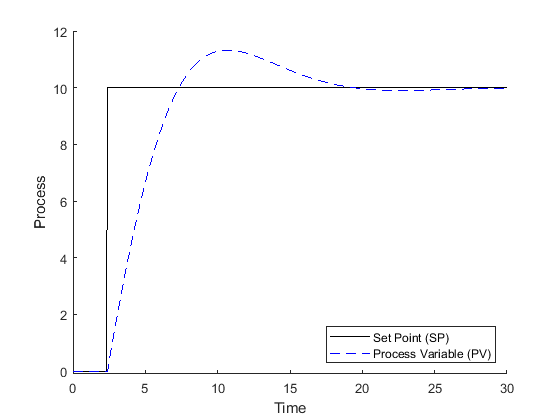



% process model
Kp = 3.0;
taup = 5.0;


% specify number of steps
ns = 300;
% define time points
t = linspace(0,ns/10,ns+1);
delta_t = t(2)-t(1);

% storage for recording values
op = zeros(1,ns+1);  % controller output
pv = zeros(1,ns+1);  % process variable
e = zeros(1,ns+1);   % error
ie = zeros(1,ns+1);  % integral of the error
dpv = zeros(1,ns+1); % derivative of the pv
P = zeros(1,ns+1);   % proportional
I = zeros(1,ns+1);   % integral
D = zeros(1,ns+1);   % derivative
sp = zeros(1,ns+1);  % set point
sp(25:end) = 10;

% PID (starting point)
Kc = 1.0/Kp;
tauI = taup;
tauD = 0.0;

% PID (tuning)
Kc = Kc * 2;
tauI = tauI / 2;
tauD = 1.0;

% Upper and Lower limits on OP
op_hi = 10.0;
op_lo = 0.0;

% loop through time steps    
for i = 2:ns
    e(i) = sp(i) - pv(i);
    if i >= 1  % calculate starting on second cycle
        dpv(i) = (pv(i)-pv(i-1))/delta_t;
        ie(i) = ie(i-1) + e(i) * delta_t;
    end
    P(i) = Kc * e(i);
    I(i) = Kc/tauI * ie(i);
    D(i) = - Kc * tauD * dpv(i);
    op(i) = op(1) + P(i) + I(i) + D(i);
    if op(i) > op_hi  % check upper limit
        op(i) = op_hi;
        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup
    end
    if op(i) < op_lo  % check lower limit
        op(i) = op_lo;
        ie(i) = ie(i) - e(i) * delta_t; % anti-reset windup
    end
%     y = odeint(process,pv(i),[0,delta_t],args=(op(i),Kp,taup));
    [a, y] = ode45(@(a, y) process(a, y, op(i), Kp, taup), [0,delta_t], pv(i));
    
    pv(i+1) = y(end);
end

figure(1);
hold on

p1 = plot(t,sp,'k-');
p2 = plot(t,pv,'b--');
legend([p1, p2],{'Set Point (SP)','Process Variable (PV)'}, 'Location', 'southeast')
ylabel('Process')
ylim([-0.1,12])
xlabel('Time')

function dydt = process(a,y,u,Kp,taup)
    % Kp = process gain
    % taup = process time constant
    dydt = -y/taup + Kp/taup * u;
end

% plot results
